# **Análisis y síntesis LPC**

addpath('./Datos')
addpath('./Funciones/')

load LPCpar.mat
load VQsTarea3.mat

## **TAREA 4.A**

Para cada VQ diseñado anteriormente, y con los ficheros de tvg_home_8khz y tvg_muller_8khz, escuchad la señal reconstruída y calculad la SNR global. Utilizad Lframe=160. ¿Por cuál o cuáles de los VQs os decantaríais?

[s_home fs_home] = audioread('tvg_home_8khz.wav');
[s_muller fs_muller] = audioread('tvg_muller_8khz.wav');
sound(s_home);

p = 10;
Lframe = 160;

### Para tvg_home_8khz:

[synhome_LPC, dhome_LPC] = syslpc_vq (s_home, Lframe, p, VQLPC, 'LPC');

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


[synhome_RC, dhome_RC] = syslpc_vq (s_home, Lframe, p, VQRC, 'RC');
[synhome_LAR, dhome_LAR] = syslpc_vq (s_home, Lframe, p, VQLAR, 'LAR');
[synhome_LSF, dhome_LSF] = syslpc_vq (s_home, Lframe, p, VQLSF, 'LSF');


%Calculamos SNR para ver que cuantificación es la preferible en este caso
SNRhome_LPC = SNR(s_home(1:length(synhome_LPC),:), synhome_LPC)

SNRhome_LPC = 2.3718

SNRhome_RC = SNR(s_home(1:length(synhome_RC),:), synhome_RC)

SNRhome_RC = 1.8812

SNRhome_LAR = SNR(s_home(1:length(synhome_LAR),:), synhome_LAR)

SNRhome_LAR = 4.4765

SNRhome_LSF = SNR(s_home(1:length(synhome_LSF),:), synhome_LSF)

SNRhome_LSF = 4.0153

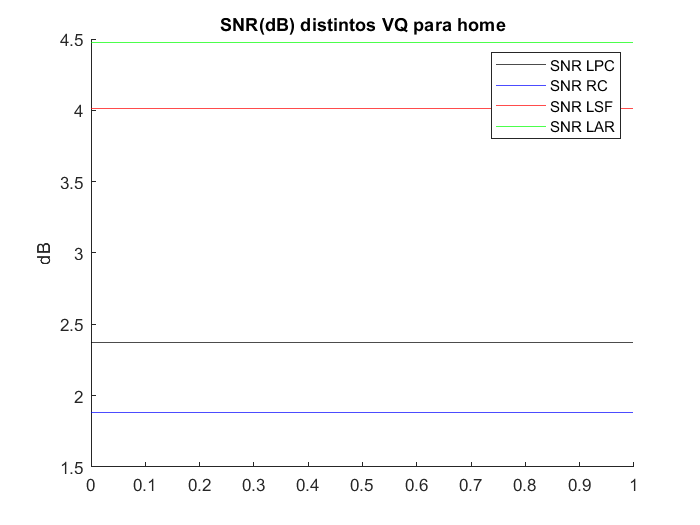

figure
yline (SNRhome_LPC, 'k')
hold on
yline (SNRhome_RC, 'b')
hold on
yline (SNRhome_LSF, 'r')
hold on
yline (SNRhome_LAR,'g')
hold off

ylabel('dB')
legend({'SNR LPC', 'SNR RC', 'SNR LSF', 'SNR LAR'})
title(sprintf('SNR(dB) distintos VQ para home'));

### Para tvg_muller_8khz:

[synmuller_LPC, dmuller_LPC] = syslpc_vq (s_muller, Lframe, p, VQLPC, 'LPC');
[synmuller_RC, dmuller_RC] = syslpc_vq (s_muller, Lframe, p, VQRC, 'RC');
[synmuller_LAR, dmuller_LAR] = syslpc_vq (s_muller, Lframe, p, VQLAR, 'LAR');
[synmuller_LSF, dmuller_LSF] = syslpc_vq (s_muller, Lframe, p, VQLSF, 'LSF');


%Calculamos SNR para ver que cuantificación es la preferible en este caso
SNRmuller_LPC = SNR(s_muller(1:length(synmuller_LPC),:), synmuller_LPC)

SNRmuller_LPC = 3.9585

SNRmuller_RC = SNR(s_muller(1:length(synmuller_RC),:), synmuller_RC)

SNRmuller_RC = 4.9651

SNRmuller_LAR = SNR(s_muller(1:length(synmuller_LAR),:), synmuller_LAR)

SNRmuller_LAR = 7.1212

SNRmuller_LSF = SNR(s_muller(1:length(synmuller_LSF),:), synmuller_LSF)

SNRmuller_LSF = 6.2650

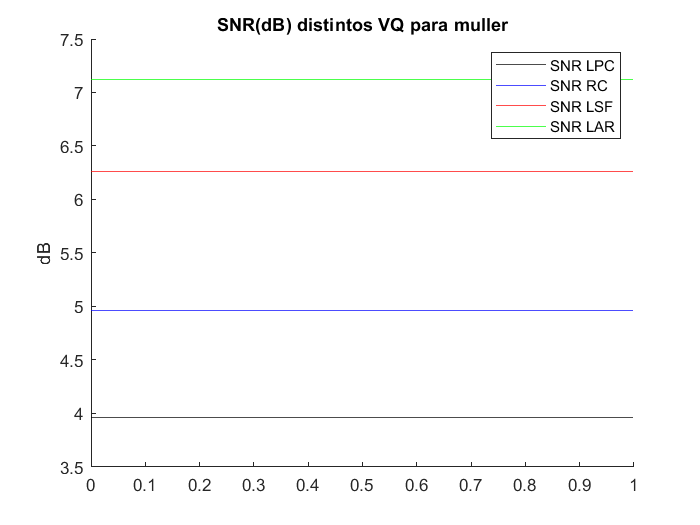

figure
 yline (SNRmuller_LPC, 'k')
 hold on
yline (SNRmuller_RC, 'b')
hold on
yline (SNRmuller_LSF, 'r')
hold on
yline (SNRmuller_LAR,'g')
hold off

ylabel('dB')
legend({'SNR LPC', 'SNR RC', 'SNR LSF', 'SNR LAR'})
title(sprintf('SNR(dB) distintos VQ para muller'));

%sound(synhome_LPC, fs_home)
%sound(synhome_RC, fs_home);
%sound(synhome_LSF, fs_home);
%sound(synhome_LAR, fs_home);
%sound(synmuller_LPC, fs_home)
%sound(synmuller_RC, fs_home);
%sound(synmuller_LSF, fs_home);
%sound(synmuller_LAR, fs_home);

## **TAREA 4.B**

Para cada VQ diseñado anteriormente, y con los ficheros de tvg_home_8khz y tvg_muller_8khz, escuchad la señal reconstruída y calculad la SNR global. ¿Os parecen lógicos los resultados obtenidos?. 

[s_home fs_home] = audioread('tvg_home_8khz.wav');
[s_muller fs_muller] = audioread('tvg_muller_8khz.wav');
sound(s_home);

p = 10;
Lframe = 160;

### Para tvg_home_8khz:

[synhome_LPC, dhome_LPC] = syslpc_vqq (s_home, Lframe, p, VQLPC, 'LPC');

LPC =     1.0000   -0.9444   -0.3193    0.1371    0.0538    0.0065   -0.0009    0.0576    0.0011    0.0293   -0.0014


[synhome_RC, dhome_RC] = syslpc_vqq (s_home, Lframe, p, VQRC, 'RC');

LPCVQ =     1.0000   -0.8200   -0.3971    0.1657    0.0509   -0.0030    0.0978   -0.0332    0.0647   -0.0541    0.0593


[synhome_LAR, dhome_LAR] = syslpc_vqq (s_home, Lframe, p, VQLAR, 'LAR');
[synhome_LSF, dhome_LSF] = syslpc_vqq (s_home, Lframe, p, VQLSF, 'LSF');


%Calculamos SNR para ver que cuantificación es la preferible en este caso
SNRhome_LPC = SNR(s_home(1:length(synhome_LPC)), synhome_LPC)

SNRhome_LPC = 316.7176

SNRhome_RC = SNR(s_home(1:length(synhome_RC)), synhome_RC)

SNRhome_RC = 316.2844

SNRhome_LAR = SNR(s_home(1:length(synhome_LAR)), synhome_LAR)

SNRhome_LAR = 306.4120

SNRhome_LSF = SNR(s_home(1:length(synhome_LSF)), synhome_LSF)

SNRhome_LSF = 311.6872

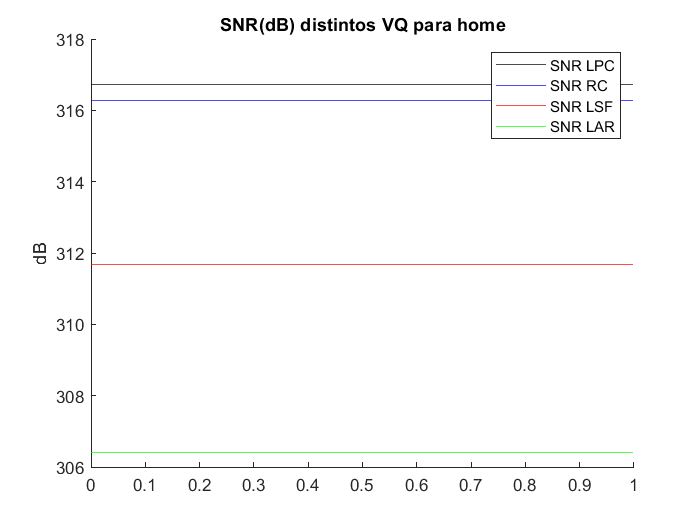

%sound(synhome_LPC, fs_home)
%sound(synhome_RC, fs_home);
%sound(synhome_LSF, fs_home);
%sound(synhome_LAR, fs_home);
figure
yline (SNRhome_LPC, 'k')
hold on
yline (SNRhome_RC, 'b')
hold on
yline (SNRhome_LSF, 'r')
hold on
yline (SNRhome_LAR,'g')
hold off

ylabel('dB')
legend({'SNR LPC', 'SNR RC', 'SNR LSF', 'SNR LAR'})
title(sprintf('SNR(dB) distintos VQ para home'));

### Para tvg_muller_8khz:

[synmuller_LPC, dmuller_LPC] = syslpc_vqq (s_muller, Lframe, p, VQLPC, 'LPC');

LPC =     1.0000   -0.0482   -0.1372    0.3809    0.7312   -0.2305   -0.2414    0.3397    0.1355   -0.1019    0.1032


[synmuller_RC, dmuller_RC] = syslpc_vqq (s_muller, Lframe, p, VQRC, 'RC');

LPCVQ =     1.0000   -0.1630   -0.1178    0.3331    0.6817   -0.2209   -0.1641    0.3006    0.0775   -0.0725    0.0826


[synmuller_LAR, dmuller_LAR] = syslpc_vqq (s_muller, Lframe, p, VQLAR, 'LAR');
[synmuller_LSF, dmuller_LSF] = syslpc_vqq (s_muller, Lframe, p, VQLSF, 'LSF');


%Calculamos SNR para ver que cuantificación es la preferible en este caso
SNRmuller_LPC = SNR(s_muller(1:length(synmuller_LPC)), synmuller_LPC)

SNRmuller_LPC = 318.6974

SNRmuller_RC = SNR(s_muller(1:length(synmuller_RC)), synmuller_RC)

SNRmuller_RC = 315.1391

SNRmuller_LAR = SNR(s_muller(1:length(synmuller_LAR)), synmuller_LAR)

SNRmuller_LAR = 314.7116

SNRmuller_LSF = SNR(s_muller(1:length(synmuller_LSF)), synmuller_LSF)

SNRmuller_LSF = 311.4040

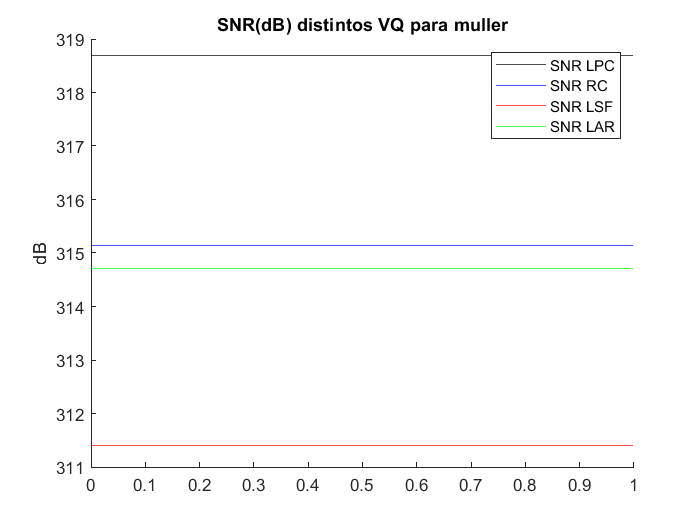

%sound(synmuller_LPC, fs_home)
%sound(synmuller_RC, fs_home);
%sound(synmuller_LSF, fs_home);
%sound(synmuller_LAR, fs_home);
figure
yline (SNRmuller_LPC, 'k')
hold on
yline (SNRmuller_RC, 'b')
hold on
yline (SNRmuller_LSF, 'r')
hold on
yline (SNRmuller_LAR,'g')

ylabel('dB')
legend({'SNR LPC', 'SNR RC', 'SNR LSF', 'SNR LAR'})
title(sprintf('SNR(dB) distintos VQ para muller'));

## TAREA 4.C

Consideraremos los ficheros test_period_70, tvg_home_8khz y tvg_muller_8khz. El primero es un fichero de test obtenido como respuesta de un filtro IIR a una entrada consistente en un tren de deltas con periodo 70 muestras. 

Procesaremos cada fichero completo con las funciones syslpc y syslpc_vqq (con VQLSF), y guardaremos en variables separadas las señales originales y sus respectivos errores de predicción.

Para cada fichero representad las siguientes figuras que contendrán tres gráficas (subplot):

- Señal test_period_70 , error de predicción obtenido con syslpc_vqq y error de predicción obtenido con syslpc en el tramo de la muestra 1000 a la 2000. 

- Lo mismo para tvg_home_8khz, representando el tramo 13500:14500. 

- Repetid para tvg_muller_8khz en el tramo 8500:9500.

Comentad razonadamente los resultados obtenidos en cada una de las gráficas. ¿Cómo afecta la cuantificación de los coeficientes de los filtros?

[s_home fs_home] = audioread('tvg_home_8khz.wav');
[s_muller fs_muller] = audioread('tvg_muller_8khz.wav');
[s_period fs_period] = audioread('test_period_70.wav');
sound(s_period);

p = 10;
Lframe = 160;

### Para test_period_70

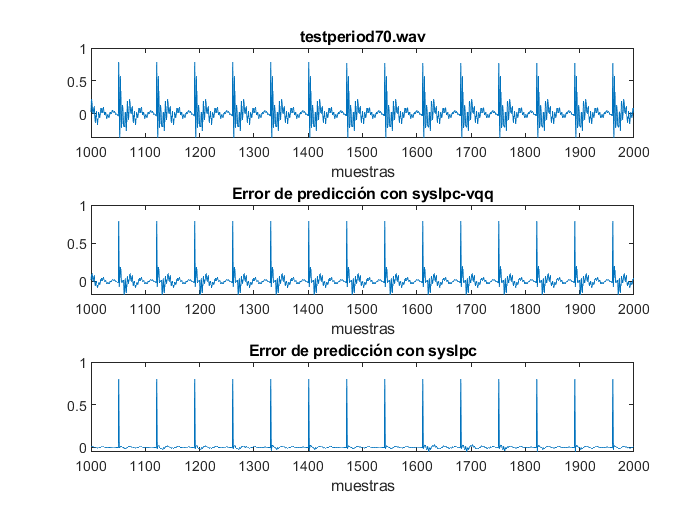

[synperiod_LSF_1, dperiod_LSF_1] = syslpc_vqq (s_period, Lframe, p, VQLSF, 'LSF');
[synperiod_LSF_2, dperiod_LSF_2] = syslpc (s_period, Lframe, p);

m = 1000:2000;
figure
subplot 311
plot (m, s_period(1000:2000))
xlabel('muestras')
title('testperiod70.wav')

subplot 312
plot(m, dperiod_LSF_1(1000:2000))
xlabel('muestras')
title('Error de predicción con syslpc-vqq')

subplot 313
plot(m, dperiod_LSF_2(1000:2000))
xlabel('muestras')
title ('Error de predicción con syslpc')

### Para tvg_home_8khz

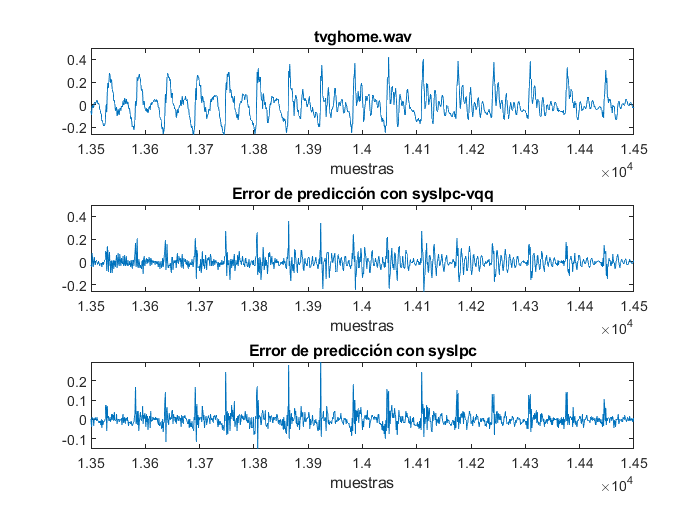

[synhome_LSF_1, dhome_LSF_1] = syslpc_vqq (s_home, Lframe, p, VQLSF, 'LSF');
[synhome_LSF_2, dhome_LSF_2] = syslpc (s_home, Lframe, p);

m = 13500:14500;
figure
subplot 311
plot (m, s_home(13500:14500))
xlabel('muestras')
title('tvghome.wav')

subplot 312
plot(m, dhome_LSF_1(13500:14500))
xlabel('muestras')
title('Error de predicción con syslpc-vqq')

subplot 313
plot(m, dhome_LSF_2(13500:14500))
xlabel('muestras')
title ('Error de predicción con syslpc')

### Para tvg_muller_8khz

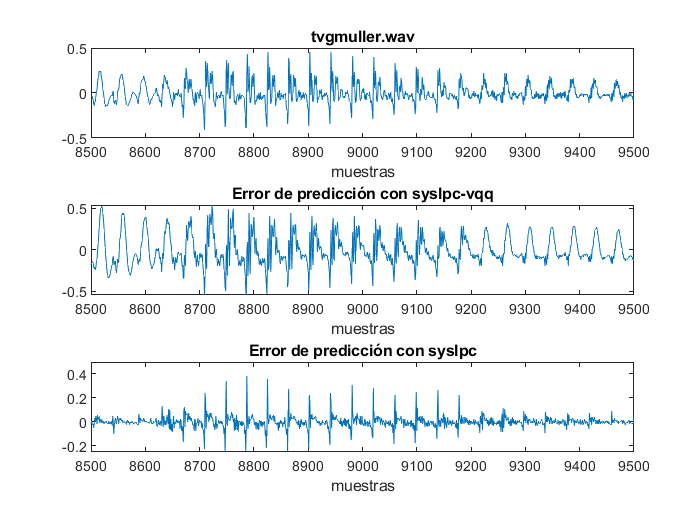

[synmuller_LSF_1, dmuller_LSF_1] = syslpc_vqq (s_muller, Lframe, p, VQLSF, 'LSF');
[synmuller_LSF_2, dmuller_LSF_2] = syslpc (s_muller, Lframe, p);

m = 8500:9500;
figure
subplot 311
plot (m, s_muller(8500:9500))
xlabel('muestras')

title('tvgmuller.wav')

subplot 312
plot(m, dmuller_LSF_1(8500:9500))
xlabel('muestras')
title('Error de predicción con syslpc-vqq')

subplot 313
plot(m, dmuller_LSF_2(8500:9500))
xlabel('muestras')
title ('Error de predicción con syslpc')